## Temperature Control Lab Activity

Vaccine production involves innoculating viral material within a host cuture. The viral meterial will denature if the temperature deviates from the setpoint at any given time for the incubation process. We will use the TCLab to simulate the incubator for the vaccine.

[Thematic Image]

To optimize the ammount of vacine produced, tune the PID to maximize time at the setpoint. First, simulate the TCLab unit and tune the parameters for the PID. Then, use the parameters from the simulation to control the temperature control lab at 40 C for 3 minutes, and 30 C for three minutes afterward.

[graph of setpoint]

## Simulation

#### PID Controller Equation


$$e(t) = SP - PV$$



$$u(t) = u_{bias} + K_ce(t) + \frac{K_c}{\tau_I}\int_0^te(t)dt-K_c\tau_D\frac{d(PV)}{dt}$$


Find values for $K_c$, $\tau_I$, and $\tau_D$ that minimize error in the simulation below.

clc; clear all; close all;
Kc = 11

Kc = 11

tauI = 2

tauI = 2

tauD =  0

tauD = 0

n = 60 * 6;

% initialize arrays
time = linspace(1, n, n);
setpoint = ones(n, 1) * 40;
setpoint(180:end) = 30;
PV = ones(n, 1) * 25;
u = zeros(n, 1);
error = zeros(n, 1);
Ierror = 0;
prev_time = 0;

min = 0;
max = 100;

for i = 1:n
    % PID Controller
    e = setpoint(i) - PV(i);
    error(i) = e;
    Ierror = Ierror + e;
    if i ~= 1
        dPVdt = (PV(i) - PV(i-1)) / (time(i) - time(i-1));
    else
        dPVdt = 0;
    end
    
    P = Kc * e;
    I = Kc / tauI * Ierror;
    D = Kc * tauD * dPVdt;
    u(i) = P + I - D;
    
    % Anti-reset windup
    if u(i) > max
        u(i) = max;
        Ierror = Ierror - e;
    elseif u(i) < min
        u(i) = min;
        Ierror = Ierror - e;
    end
    
    % heater
    PV(i+1) = arduino_sim(u(i));
end
fprintf('Error: %E deg s', Ierror)

Error: 3.588881E+00 deg s

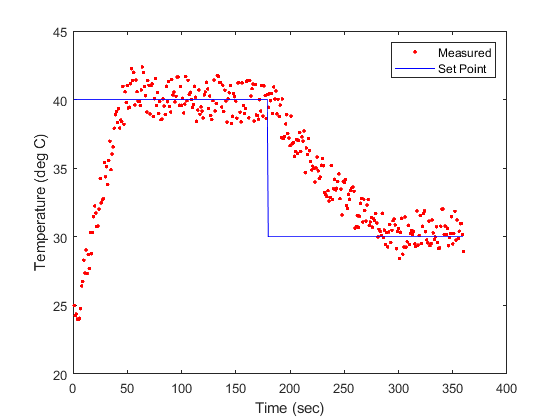


% graph
figure(1)
plot(time, PV(1:end-1), 'r.')
hold on;
plot(time, setpoint, 'b-')
hold on;
xlabel('Time (sec)')
ylabel('Temperature (deg C)')
legend({'Measured', 'Set Point'})

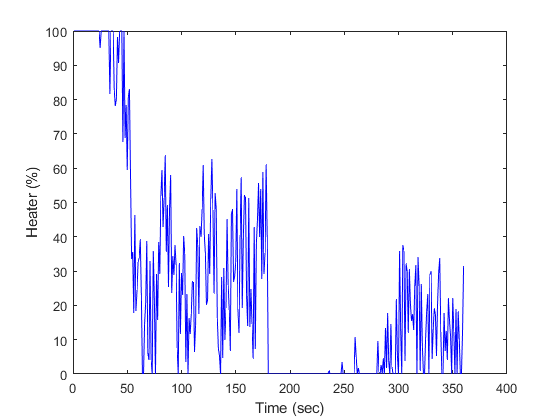


figure(2)
plot(time, u, 'b-')
xlabel('Time (sec)')
ylabel('Heater (%)')
hold off;

## Physical Verification

Verify your simulation by using the same parameters with the TCLab

Kc = 11

Kc = 11

tauI = 2

tauI = 2

tauD = 0

tauD = 0

n = 60 * 6;

% initialize arrays
time = zeros(n);
setpoint = ones(n) * 40;
setpoint(180:end) = 30;
PV = zeros(n);
u = zeros(n);
error = zeros(n);
Ierror = 0;
prev_time = 0;

min = 0;
max = 100;

lab = tclab;

Attempt to execute SCRIPT tclab as a function:
C:\Users\jhamm\OneDrive - BYU\business\RA Hedengren\MatLab\arduino\0_Test_Device\Simulink\Model_Test\tclab.m

tic
for i = 1:n
    % timer
    while toc - prev_time <1
        pause(.01)
    end
    time(i) = toc;
    prev_time = time(i);
    
    % PID Controller
    PV(i) = lab.T1;
    e = setpoint(i) - PV(i);
    error(i) = e;
    Ierror = Ierror + e;
    if i ~= 1
        dPVdt = (PV(i) - PV(i-1)) / (time(i) - time(i-1));
    else
        dPVdt = 0;
    end
    
    P = Kc * e;
    I = Kc / tauI * Ierror;
    D = Kc * tauD * dPVdt;
    u(i) = P + I - D;
    
    % Anti-reset windup
    if u(i) > max
        u(i) = max;
        Ierror = Ierror - e;
    elseif u(i) < min
        u(i) = min;
        Ierror = Ierror - e;
    end
    
    % heater
    lab.Q1(u(i));
    
    % graph
    figure(1)
    plot(time(1:i), PV(1:i), 'r.')
    hold on;
    plot(time(1:i), setpoint(1:i), 'b-')
    hold on;
    xlabel('Time (sec)')
    ylabel('Temperature (deg C)')
    legend({'Measured', 'Set Point'})
    
    figure(2)
    plot(time(1:i), u(1:i), 'b-')
    xlabel('Time (sec)')
    ylabel('Heater (%)')
    hold off;
    
end

% Functions for later use
% Ardiono ODE

function dTdt = arduino_ode(time,T,heater)

% mass
m = 0.001; % kg (2 gm)
% heat transfer coefficient
h = 200; % W/m^2-K
% surface area
A = 2 / 100^2; % m^2
% heater input
alpha = 0.022; % W/(heater input)
% heat capacity
Cp = 4900.0; % J/kg-K

% approximate time constant
%tau = m*Cp/(h*A);
%disp(['Time constant: ' num2str(tau)])

% ambient temperature
Ta = 23 + 273.15; % K
% heater = 100;
dTdt = (h*A * (Ta - T) + alpha * heater) / (m*Cp); 

end
function TC = arduino_sim(heater)

persistent T0 icount

if (isempty(icount)),
    % set initial condition
    T0 = 23+273.15;
    icount = 0;
end

% increment counter
icount = icount + 1;
time = [0,1];
[time,T] = ode15s(@(t,x)arduino_ode(t,x,heater),time,T0);
TK = T(end);
T0 = TK;

noise = (rand()-0.5)*3.0;
TC = TK - 273.15 + noise;

end